# **EEE30004 - Digital Signal Processing**

# **Minor Project Submission**

# Name: Sulekh Kulatunga    ID:103156087

# Introduction

License plate text extraction from images is a vital task within the domain of computer vision and image processing. This project focuses on the application of image processing techniques, including preprocessing and blob detection, to effectively isolate and crop letter text from car license plates. The outcome of this effort has a wide range of practical applications, spanning automated toll collection, parking management, law enforcement, and traffic analysis.

### Background

The image processing toolbox within MATLAB provides a robust environment for tackling such tasks. MATLAB offers a suite of tools for preprocessing operations like noise reduction, contrast enhancement, and image resizing, which are essential for enhancing the quality and accuracy of license plate text extraction. In addition to these operations, we will harness the concept of blob detection, a fundamental aspect of computer vision, to identify text regions on license plates, despite challenges such as variations in lighting conditions, perspective distortions, and image noise.

### **Project Aim **

The primary aim of this project is to develop an image processing pipeline that can reliably and accurately extract text from license plates in a variety of real-world scenarios. Specifically, we aim to:

- Detect License Plate Regions: Implement preprocessing techniques to enhance images and identify regions of interest that potentially contain license plates.

- Locate Text Blobs: Utilize blob detection algorithms to precisely locate and isolate the letter text on license plates within the identified regions.

- Crop and Extract Text: Develop algorithms to crop and extract the text from license plates, ensuring it is ready for further analysis or recognition.

### Potential Use Cases

The successful execution of this project holds immense promise across multiple domains, with potential applications including:

- Automated Toll Collection: Streamlining toll collection processes by automating license plate identification and record-keeping.

- Efficient Parking Management: Enhancing the efficiency of parking facilities through automated entry and exit systems based on license plate recognition.

- Improved Law Enforcement: Empowering law enforcement agencies with improved surveillance and vehicle tracking capabilities.

- Enhanced Traffic Analysis: Contributing to traffic management and analysis systems, optimizing traffic flow, detecting violations, and improving overall road safety.

- Enhanced Access Control: Strengthening security in gated communities and corporate campuses through reliable license plate recognition for access control.

This project represents a significant step toward leveraging MATLAB's image processing capabilities to address real-world challenges, offering automation, efficiency, and enhanced security in various domains. In the following sections, we will delve into the implementation details of our image processing pipeline, showcasing the potential of this technology in practice.

# Algorithm

The MATLAB program begins by importing the license plate image and applying a series of preprocessing steps. It first converts the image to grayscale and then to binary to simplify subsequent processing. Next, it performs horizontal edge detection using the Canny algorithm and applies the Hough transform to identify horizontal lines on the plate. Similarly, vertical edge detection and Hough transform are applied to detect vertical lines. The results from both the horizontal and vertical transforms are used to crop the original image, isolating the plate area.

Subsequently, the program conducts morphological filtering and median filtering to enhance the cropped image's quality. Blob analysis is then performed to identify distinct letter regions within the image. The program utilizes statistical processing with the k-means algorithm to determine the distribution of letter heights in the image, providing an estimate of letter height.

Using this estimated letter height, the program separates the letter blobs from the image, and further processing is applied to remove any duplicate blobs. The individual letter regions are then cropped from the image using the horizontal and vertical coordinate properties obtained from the blob analysis.

Finally, the program subjects each individual letter region to template matching, where it compares the extracted letters to a database of template letters to recognize the specific letter represented by each blob. This comprehensive process allows the program to extract and identify the text stored within the license plate image efficiently.

# **Code**

**All the figure used to display code demonstrations were done with the **`plate7.jpg `**image. The results are replicable across the other included images. **

## Part 1: Image Initialization 

close all;clear; clc; % Workspace initialization, starting from clean slate
letter_templates=imageDatastore("Template_letters");

text_plate_letters="";
car_plate="Car_plate_numbers\plate7.jpg";


plate=blackandwhite(car_plate);
plate=oddandeven(plate);
original_plate=plate;

The MATLAB workspace is cleared, and the image is imported, and preprocessed using the `blackandwhite``() `and `oddandeven``()` functions. `blackandwhite`() converts a color image of a plate, into a logical black and white image, while `oddandeven()` returns an image matrix that's resized so both its dimensions are odd, so that it can be used in image processing algorithms present later in the program. 

## Part 2: Horizontal Edge Detection 

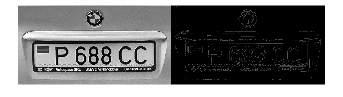

edges=icanny(plate);
figure, montage({plate, edges}) ; 

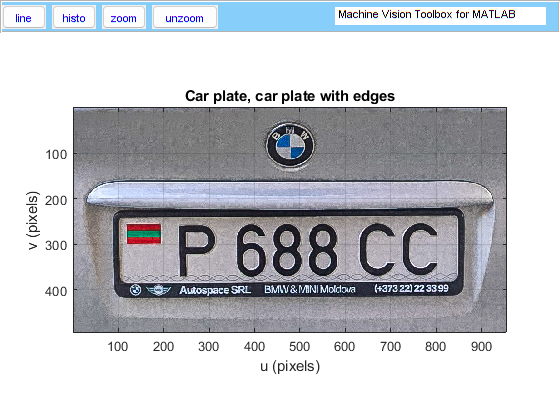

grid on , axis on, title('Car plate, car plate with edges') ;

The `canny` edge algorithm is used on the processed logical plate image to detect edges present in the text. `icanny` output is then displayed. 

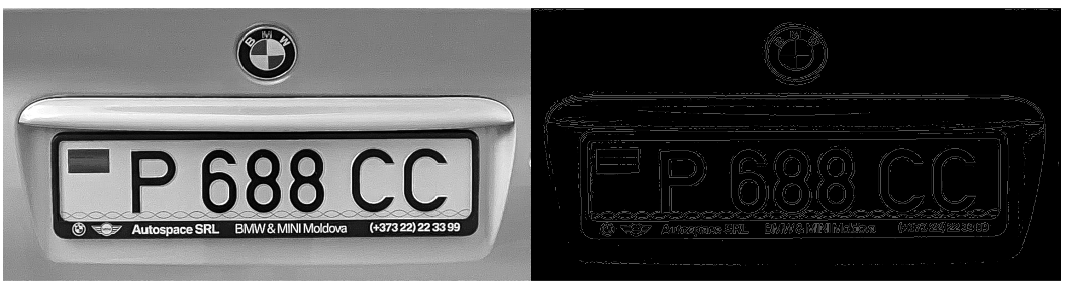

 
%% Find Hough Horizontal edges
h = Hough(edges)

 
h = 
 
Hough: nd=401, ntheta=400, interp=3x3, distance=1
 


figure, h.show(), grid on ,
lines = h.lines()

 
lines = 
 
theta=-2.27421e-06, rho=161.486, strength=1      
theta=0.00824367, rho=381.382, strength=0.782497 
theta=-0.00032678, rho=398.205, strength=0.724582
theta=0.0173277, rho=408.734, strength=0.69112   
theta=-0.00998932, rho=374.924, strength=0.657658
theta=-0.0175356, rho=364.396, strength=0.627413 
theta=-0.0179524, rho=391.465, strength=0.622265 
theta=0.0339081, rho=414.559, strength=0.621622  
theta=0.0179712, rho=168.195, strength=0.604891  
theta=0.0257644, rho=387.984, strength=0.60103   
theta=0.00764145, rho=368.357, strength=0.595238 
theta=-0.0390673, rho=370.628, strength=0.57529  
theta=-0.0184004, rho=150.94, strength=0.571429  
theta=0.0510742, rho=413.832, strength=0.559846  
theta=0.0402362, rho=398.26, strength=0.54955    
theta=-0.0395186, rho=357.535, strength=0.547619 
theta=0.0705941, rho=424.469, strength=0.545045  
theta=0.00859314, rho=224.724, strength=0.543115 
theta=-0.0588471, rho=360.151, strength=0.535393 
theta=0.0473988, rho=426.932, strengt

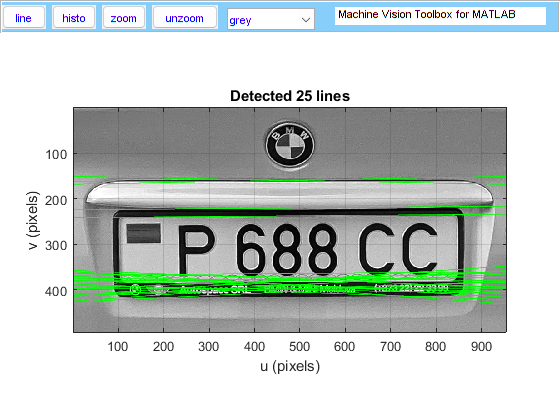

idisp(plate) , grid on, title(strcat("Detected ",string(numel(lines))," lines")) ;
h.plot('g')


% nonlocal maxima supression
h1 = Hough(edges, 'suppress', 4)

 
h1 = 
 
Hough: nd=401, ntheta=400, interp=3x3, distance=4
 


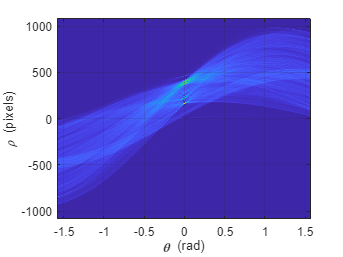

figure, h.show(), grid on ,

lines = h1.lines()

 
lines = 
 
theta=-2.27421e-06, rho=161.486, strength=1     
theta=0.00824367, rho=381.382, strength=0.782497
theta=0.0168517, rho=410.554, strength=0.69112  
theta=-0.0390673, rho=370.628, strength=0.57529 
theta=0.058912, rho=419.111, strength=0.552767  
theta=0.00859314, rho=224.724, strength=0.543115
 


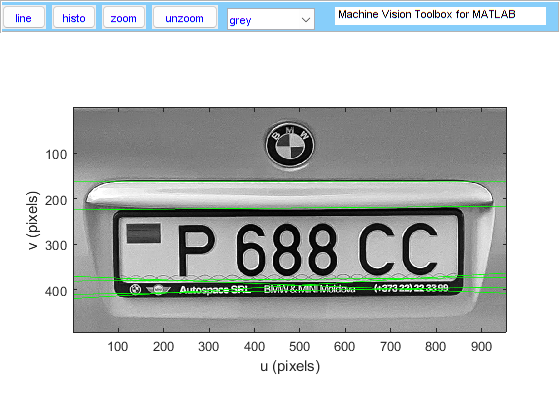

figure, idisp(plate);
h1.plot('g')

In this MATLAB code segment, the Hough transform is applied to an edge-detected image represented by the variable `edges`. The `h` object represents the Hough transform results. It then proceeds to visualize the Hough transform results by displaying detected lines over the original image using `idisp(plate)`. The number of detected lines is shown in the title of the image. These lines are plotted in green.

Following this, a modified Hough transform `h1` is computed, with a non-local maxima suppression parameter set to 4.

 The code again displays the detected lines over the original image and plots them in green. Subsequently, it calculates gradients and identifies lines with low slopes, storing their information in the `rho_lines` array.

Overall, this code segment focuses on applying the Hough transform to detect lines in the input image, visualize them, and perform non-local maxima suppression to refine the line detection results.

## Part 3: Horizontal Edge Image Cropping

gradient=lines.rho.*tan(deg2rad(lines.theta));
low_slopes=find((-0.1<=gradient) & (gradient<=0.1));
rho_lines=zeros(numel(low_slopes),2);

for n=1:numel(low_slopes)
    rho_lines(n,1)=lines(low_slopes(n)).rho;
    rho_lines(n,2)=low_slopes(n);
end

figure, idisp(plate) ; grid on,

rho_lines=sortrows(rho_lines,1);

disp("Calculating differences")

Calculating differences


for n = 1:height(rho_lines)
    v_point1=rho_lines(n,1); 
    v_point2=rho_lines(n+1,1);
    difference(n)=v_point2-v_point1;
    disp(difference(n))
    if n==(height(rho_lines)-1)
        break
    end
end

   63.2382

  156.6580



In this section, a gradient map is computed based on the Hough-transformed lines' parameters, specifically the rho and theta values. Subsequently, the code identifies "low-slope" lines by filtering those within a certain range of slopes, represented by the gradient values.

A matrix called `rho_lines` is then initialized to store information about these low-slope lines. In a loop, each line's rho value and its corresponding index are recorded and stored in this matrix.

The code proceeds to visualize the original image using `idisp(plate)` while overlaying a grid for reference.

The `rho_lines` matrix is sorted in ascending order based on the first column (rho values).

Next, the code calculates and displays the differences between consecutive rho values, essentially determining the spacing or gaps between these low-slope lines in the image. This is done to crop the plate section with the letters in-between the high and low horizontal edges, based upon the assumption that the 2 vertical edges with the highest difference, have to be the top and bottom of the plate within the image

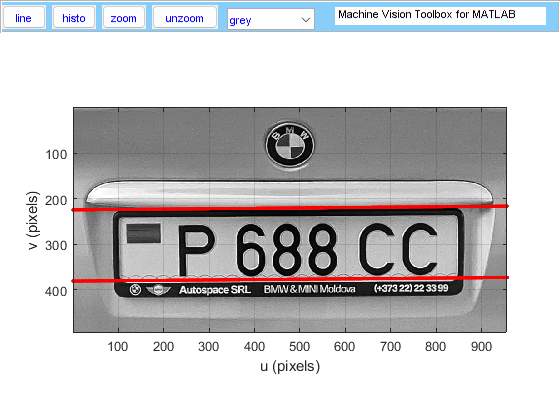


Nj=find(difference==max(difference));


lines(rho_lines(Nj,2)).plot('r.');
lines(rho_lines(Nj+1,2)).plot('r.');


horizontalpoint1=lines(rho_lines(Nj,2)).rho;
horizontalpoint2=lines(rho_lines(Nj+1,2)).rho;

%cropped_image=plate(lines(rho_lines(Nj,2)).rho:lines(rho_lines(Nj+1,2)).rho,:,:);
cropped_image=plate(horizontalpoint1:horizontalpoint2,:,:);

figure
idisp(cropped_image);
title("Cropped version");

The code then identifies the index `Nj` where the maximum difference occurs, representing the gap between two horizontal lines. It marks these lines in red on the original image using the `lines` object.

 Finally, it calculates the rho values at these points to define a cropping region for the car plate. The code then crops the image to extract this region, resulting in a cropped version of the car plate, which is displayed in a separate figure.

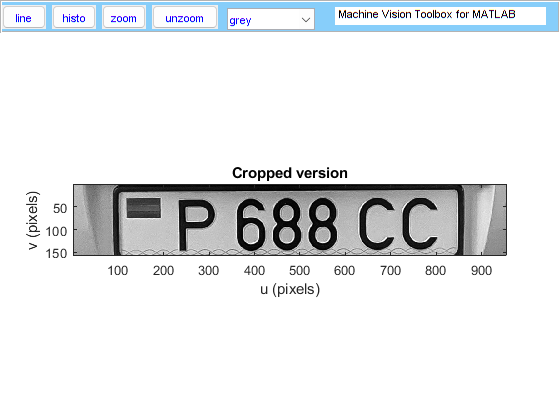

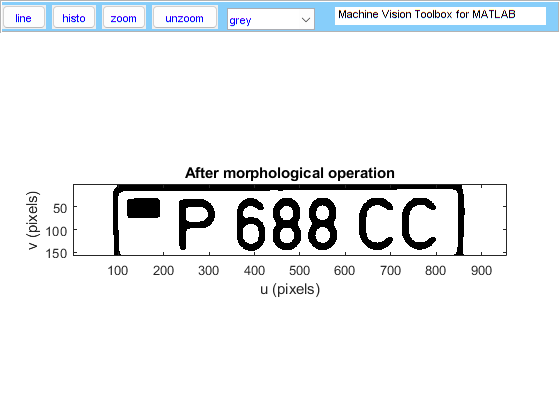

plate=morphology(cropped_image,round(lines(rho_lines(Nj+1,2)).rho-lines(rho_lines(Nj,2)).rho));

%plate=morphology(cropped_image,300);

plate=medfilt2(plate, [4 4]);

The plate then undergoes binary morphology. With the function `morphology()``, `the image undergoes closing, with a structural element based on the height of the plate section. 

## Part 3: Vertical Edge Detection

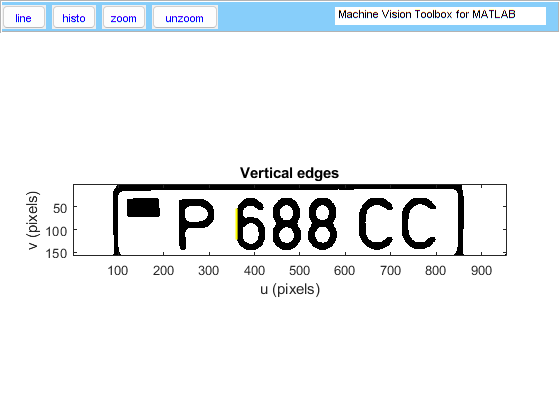

%% Vertical Hough edge transform

vertical_edges = edge(plate, 'Sobel', 'vertical');

% nonlocal maxima supression
[H,T,R]=hough(vertical_edges);
P  = houghpeaks(H,5,'threshold',ceil(0.6*max(H(:))));
lines = houghlines(vertical_edges,T,R,P,'FillGap',5);

for n=1:numel(lines)
    plate_vertical=insertShape(double(plate),'line',[lines(n).point1(1),lines(n).point1(2),lines(n).point2(1),lines(n).point2(2)],LineWidth=5);
end
figure
idisp(plate_vertical);
title("Vertical edges")

A vertical edge transform is performed on the `plate` image using the Sobel operator. This operation identifies vertical edges in the image, highlighting regions where there are rapid changes in intensity along the vertical direction.

Following the edge detection, a Hough transform is applied to the vertical edges to detect lines within the image. This process involves identifying peaks in the Hough transform space, which represent lines in the original image. These peaks are obtained using the `houghpeaks` function and are based on a specified threshold.

Subsequently, the code extracts the lines found using the Hough transform and stores them in the `lines` variable. Each line is represented by its starting and ending points.

Finally, the code visualizes the detected vertical edges and the identified lines by overlaying them on the original `plate` image, illustrated with faint lines of yellow. This step provides a visual representation of the vertical edges and the lines detected within the image, helping in the analysis and understanding of the image's content.

## Part 4: Vertical Edge Image Cropping

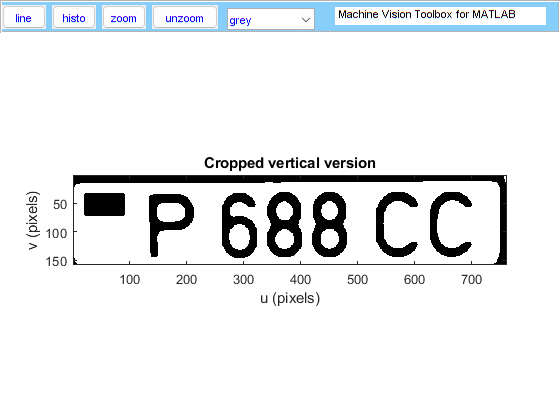

max_difference=0;
index=0;
for n=1:numel(lines)
    difference=abs(lines(1).point1(1)-lines(n).point1(1));
    if difference>max_difference
        max_difference=difference;
        index=n;
    end
end

verticalpoint1=lines(1).point1(1);
verticalpoint2=lines(index).point1(1);
plate=plate(:,min(verticalpoint1,verticalpoint2):max(verticalpoint1,verticalpoint2),:);
figure
idisp(plate);
title("Cropped vertical version");

Subsequently, the code calculates the maximum difference in the horizontal position of the line endpoints. Once again, the vertical edges are determined, **with the assumption that the first vertical  edge detected is always the plate boundary, and that the vertical edge from the first point, with the highest difference must be the other edge side**. Therefore, the lines with the greatest horizontal displacement is identified as the most significant vertical line within the image. The horizontal positions of this line's endpoints (`verticalpoint1` and `verticalpoint2`) are determined for further processing and cropping. This section essentially focuses on identifying and characterizing the dominant vertical features within the image, which is essential for later image cropping and analysis.

## Part 5: Final Image Preprocessing 

%% Creating final image for blob analysis
plate=original_plate(horizontalpoint1:horizontalpoint2,min(verticalpoint1,verticalpoint2):max(verticalpoint1,verticalpoint2),:);

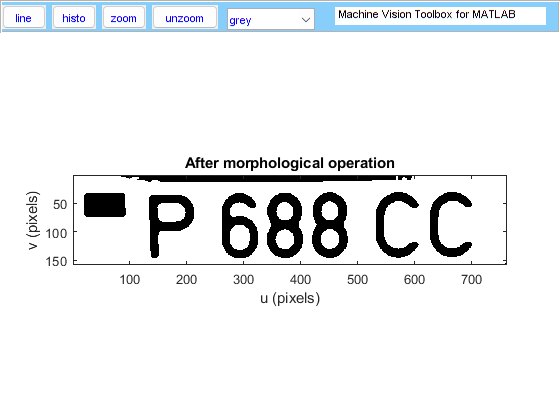

plate=morphology(plate,round(abs(horizontalpoint1-horizontalpoint2)));

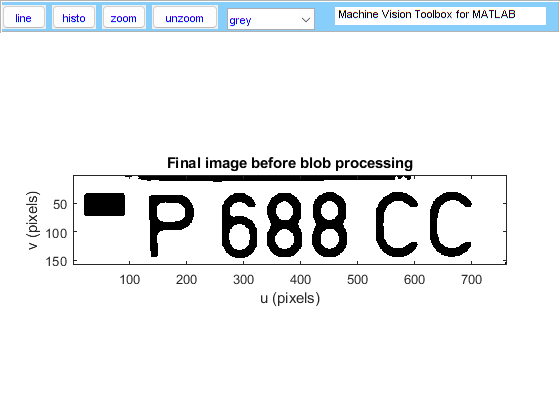

plate=medfilt2(plate, [4 4]);
figure
idisp(plate);
title("Final image before blob processing");

One last bit of image processing is done. The previous morphological binary output is no longer valid, due to the filtering being based only on the vertical height between plate edges. While the results were suitable enough for the Hough edge detections, the artifacts introduced are noticeable, so morphology has to be redone on the cropped image. The horizontal and vertical edges are used to crope the `original_plate` variable declared at the start. Median filtering with a 4x4 array is then applied to the image to remove any leftover artifacts. 

## Part 6: Blob Analysis

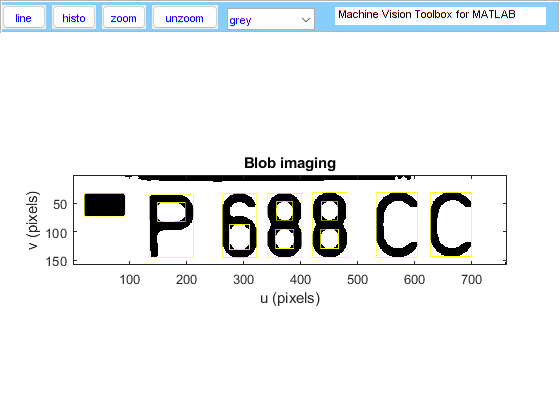

%% Finding blobs in image, identifying letters, reordering them, 
figure
idisp(plate)
title("Blob imaging")
letters=iblobs(plate);
for n=1:numel(letters)
    if letters(n).touch==0
        letters(n).plot_box('y')
        letter_heights(n)=(letters(n).vmax-letters(n).vmin);
    end
end

In this section ,individual letters are identified and isolated within the given `plate` image. The image is first displayed, and the process is visualized with the title "Blob imaging." The code utilizes the `iblobs` function from Peter Corke's robotics toolbox library to detect and represent individual letter-like regions within the image.

A loop iterates through the detected `letters`, and for each letter that is not touching another, it highlights the letter by plotting a yellow box around it using the `plot_box()` function. The condition statement `if letters(n).touch==0,` prevents the detection of faulty blobs which are in contact with the edges of the image, i.e black plate boundaries that escape the morphological filtering.  Additionally, the height of each detected letter is calculated as the difference between its maximum (`vmax`) and minimum (`vmin`) vertical positions and stored in the 'letter_heights' array. 

The purpose of the blob analysis, is to find the distribution of heights of blobs detected, determine the height of a plate letter in the image, and use it to crop the letters individually out of the overall image. 

## Part 7: Statistical Blob Height Selection

% Choose the number of clusters (K)
K = 4; % You need to decide the number of clusters

% Perform k-means clustering
[idx, centers] = kmeans(letter_heights, K);

% Initialize arrays to store cluster heights and cluster sizes
cluster_heights = zeros(1, K);
cluster_sizes = zeros(1, K);

max_cluster_size = 0; % Initialize maximum cluster size
max_cluster_height = 0; % Initialize maximum cluster height
max_valid_cluster_size = 12;


% Calculate the mean height for each cluster and count cluster sizes
for k = 1:K
    cluster_indices = (idx == k);
    cluster_heights(k) = mean(letter_heights(cluster_indices));
    cluster_sizes(k) = sum(cluster_indices);

    if cluster_sizes(k) < max_valid_cluster_size
        if cluster_sizes(k) > max_cluster_size
            max_cluster_size = cluster_sizes(k);
            max_cluster_height = cluster_heights(k);
        end
    end
end

% Display the estimated letter heights and cluster sizes
fprintf('Estimated Letter Heights and Cluster Sizes:\n');

Estimated Letter Heights and Cluster Sizes:


for k = 1:K
    fprintf('Cluster %d: Height=%.2f, Size=%d\n', k, cluster_heights(k), cluster_sizes(k));
end

Cluster 1: Height=111.25, Size=4
Cluster 2: Height=0.00, Size=4
Cluster 3: Height=35.71, Size=7
Cluster 4: Height=113.00, Size=2



%letter_height=cluster_heights(find(cluster_heights==max(cluster_heights(find(cluster_sizes<9)))));
letter_height=max(cluster_heights(find(cluster_sizes<9)));
%letter_height=300;

For the height selection process, a process of k-means clustering is performed on a set of letter heights (`letter_heights`). The number of clusters (`K`) is set to 4, and k-means clustering is applied to group the letter heights into these clusters. The code initializes arrays to store cluster heights and sizes and sets maximum cluster size and height to zero. It also defines a maximum valid cluster size threshold.

This cluster method was chosen in particular for its ability to group clusters of different types together. The idea behind this statistical model is that the blob heights of the letters, remaining artifacts that managed to escape filtering, and plate edges would all be grouped into separate clusters. With the maximum plate letter number being 9 letters, clusters with numbers higher than that are removed. Finally, from the remaining clusters, the one with the highest average has to be the leftover letters. 

For each cluster (from 1 to K), the code calculates the mean height of the letters within that cluster and counts the number of letters in the cluster. It then checks if the cluster size is below a maximum valid threshold and whether it's the cluster with the maximum size among those meeting the threshold criteria. The final part of the code displays the estimated letter heights and cluster sizes, and assigns a cluster average that fulfills all the necessary conditions as the `letter_height`.

`Cluster 1: Height=35.71, Size=7`

`Cluster 2: Height=111.25, Size=4`

`Cluster 3: Height=0.00, Size=4`

`Cluster 4: Height=113.00, Size=2`

## `Part 8: Further Blob processing`

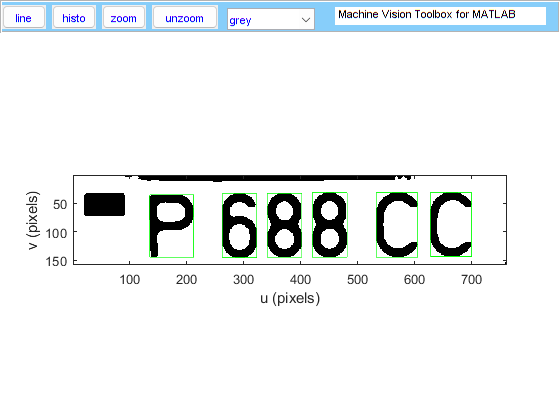

figure
idisp(plate)

plate_letters=RegionFeature.empty(0);


position=1;
for n=1:numel(letter_heights)
    letter_centre=[letters(n).uc, letters(n).vc];
    if abs(((letter_heights(n)-letter_height)/letter_height)*100) <=50.0
        plate_letters(position)=letters(n);
        letters(n).plot_box('g');
        position=position+1;
    end
end

The variable `plate` is displayed to show the results of the blob filtering. a data structure named `plate_letters` is initialized as an empty array of RegionFeature objects. 

The subsequent code iterates through a collection of letter heights stored in the variable `letter_heights`. For each height, it calculates the vertical center of the corresponding letter, considering the differences in height compared to a reference value `letter_height`. If the absolute percentage difference between the letter's height and the reference height is less than or equal to 50.0%, the letter is considered a potential candidate and is added to the `plate_letters` collection. Additionally, the code plots a green box around the selected letters in the displayed image using `letters(n).plot_box('g')`.

plate_letters = sortPlateLettersByValue(plate_letters);

The blobs are then ordered using the `sortPlateLettersByValue``() `function, in order of their appearance from left to right. 


for n=1:numel(plate_letters)
    possible_letter=plate_letters(n);
    if n==1
        plate_letters(n)=possible_letter;
    end
    if n~=1
        percentage_difference= abs((possible_letter.uc-plate_letters(n-1).uc)/plate_letters(numel(plate_letters)).uc)*100;
        if percentage_difference<=7
            disp("Same letter")
            if possible_letter.area > plate_letters(n-1).area
                plate_letters(n-1)=[];
            end
            if possible_letter.area < plate_letters(n-1).area
                plate_letters(n)=[];
            end
        end
    end
    if n >= numel(plate_letters)
        break
    end
end

nonEmptyIndices = ~arrayfun(@isempty, plate_letters);

% Resize the array to remove empty elements
plate_letters = plate_letters(nonEmptyIndices);


Finally, duplicate blobs are removed from the image. The structure of the blob detection algorithm is such that blobs present in the empty spaces of letters such as 'O', 'P' and 'Q', are prone to be detected and falsely included in the array. The for loop iterates over every letter in the `plate_letters(n)` array, by checking the percentage difference between the horizontal centroid co-ordinate of sequential elements in the array.

 If the `percentage_difference `is negligible, this proves that it is a blob within a blob. The subsequent if statements decide that depending on whether the previous or current element has a higher blob area, the faulty element position is made empty. using the `arrayfun()` element, all non-real elements are removed from the array.

## Part 9: Individual letter cropping

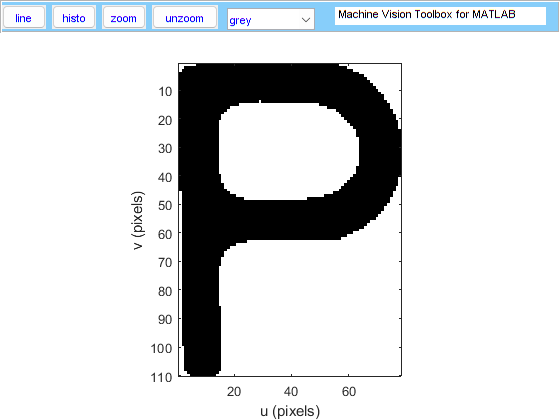

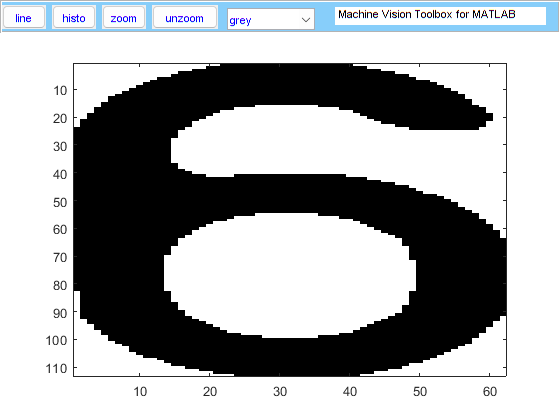

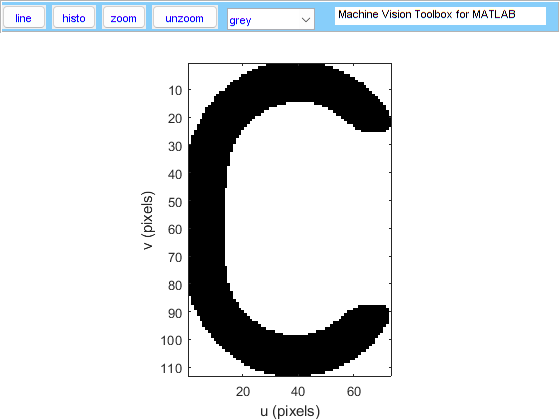

plate_letter_collection=cell(length(plate_letters), 1);

figure
title("Letter")
for n=1:numel(plate_letters)
    plate_letter_collection{n}=plate(plate_letters(n).vmin:plate_letters(n).vmax,plate_letters(n).umin:plate_letters(n).umax,:);
    idisp(plate_letter_collection{n});
    pause(1);
end

A cell array called `plate_letter_collection` is created to store individual letter images extracted from a license plate. A loop iterates through the detected plate letters, and for each letter, a specific region of the original license plate image is cropped based on the bounding box coordinates defined by `vmin`, `vmax`, `umin`, and `umax` attributes of each detected letter. These cropped letter images are then added to the `plate_letter_collection` cell array. 

Additionally, the code displays each cropped letter image using `idisp()` and introduces a brief pause of 1 second between each display, allowing the user to visualize and inspect the extracted letter images. This process enables the isolation and collection of individual characters from the license plate for subsequent processing and recognition

## Part 10: Hypothetical Template Matching

%% Iterating over every letter in the blob image matrix to find template letter with highest match

matches=findBestMatches(plate_letter_collection, letter_templates);
text="";
for n=1:numel(matches)
    text=strcat(text,stringsplitter(matches{n}));
end

disp(text);

000000



%% Function Definitions

The folllowing code was a hypothetical addition that was planned. Template matching algorithms such as `zncc (`Zero mean cross correlation`), `and `immse (`Mean-squared error`) `were to be used in the `findBestMatches``()` algorithm, but so far limited success. Using the `letter_templates` datastore, `findBestMatches `returns an array of file addresses of the template images that are locally stored. However, so far **very** limited success was observed. Future `ocr()` implementation would have to be used. 

## Functions 

### blackandwhite

function [image]=blackandwhite(input)
plate=iread(input,'double');
gs = im2gray(plate);
gs = imadjust(gs);
H = fspecial("average",2);
gs = imfilter(gs,H,"replicate");
image=gs;
figure
idisp(plate);
title('before');
end

It is responsible for converting a given input image to a black and white representation while applying several image processing operations. First, it reads the input image and converts it to a double precision format. Then, it transforms the image to grayscale using the `im2gray` function and further enhances it through contrast adjustment with `imadjust`. The function applies an averaging filter using `fspecial` to smooth the image and reduce noise. Finally, it displays the original input image using `idisp` and adds a title to the displayed image indicating it's the "before" state. The primary objective of this function is to prepare the image for subsequent image processing tasks by converting it to grayscale and enhancing its visual quality.

### morphology

function [image]=morphology(input,height)
gs=input;
SEdisk = strel("rectangle",[height width(input)]);
%Ibg = imopen(gs,SEdisk);
Ibg = imclose(gs,SEdisk);
gsSub =  Ibg - gs;
gfilter=kgauss(2);
gsSub=iconv(gfilter,gsSub);
BW = ~imbinarize(gsSub);
BW=medfilt2(BW,[10,10]);
image=BW;
figure
idisp(image);
title('After morphological operation');
end

It performs a series of morphological operations on an input image. It begins by applying a rectangular structuring element to the image, followed by morphological closing, which helps remove small gaps and irregularities in the image. The difference between the original image and the morphologically processed image is computed to highlight the areas of interest. A Gaussian filter is then applied to further refine the image. After converting it to binary using a thresholding operation, median filtering is employed to reduce noise. The processed binary image is returned as the output, and a visualization of the result is displayed, labeled as "After morphological operation."

### blackandwhiteletter

function [image]=blackandwhiteletter(input)
plate=iread(input,'double');
gs = im2gray(plate);
gs = imadjust(gs);
H = fspecial("average",2);
gs = imfilter(gs,H,"replicate");
gs=imbinarize(gs);
image=gs;
figure
idisp(plate);
title('before');
end

It performs grayscale conversion and binarization on an input image. It first reads the input image and converts it to grayscale, followed by contrast adjustment and the application of an averaging filter for noise reduction. Then, it binarizes the image to create a black-and-white representation. Finally, it displays the original image along with the processed result for visual comparison.

### sortPlateLettersByValue

function [plate_letters] = sortPlateLettersByValue(plate_letters)
    % Extract the values from the objects into a numerical array
    letter_positions = [plate_letters.uc];

    % Sort the values in ascending order and obtain the sorted indices
    [sortedValues, sortedIndices] = sort(letter_positions);

    % Rearrange the objects based on the sorted indices
    plate_letters = plate_letters(sortedIndices);
end


It takes an array of plate letter objects as input. It extracts the horizontal positions (values) of these objects and sorts them in ascending order, while also obtaining the corresponding indices of the sorted values. Then, it rearranges the plate letter objects based on these sorted indices, effectively reordering them according to their horizontal positions. This function ensures that the plate letters are organized from left to right on the license plate.

### oddandeven

function [your_matrix]=oddandeven(image)
[rows, cols] = size(image);
% Check if either dimension is even
if mod(rows, 2) == 0 || mod(cols, 2) == 0
    % If either dimension is even, make it odd
    if mod(rows, 2) == 0
        rows = rows + 1; % Increase the number of rows by 1
    end
    if mod(cols,2) == 0
        cols = cols + 1; % Increase the number of columns by 1
    end

    % Create a new matrix with the odd dimensions
    new_matrix = ones(rows, cols);

    % Copy the data from the old matrix to the new one
    new_matrix(1:size(image, 1), 1:size(image, 2)) = image;

    % Replace the old matrix in the workspace with the new one
    your_matrix = new_matrix;
else
    your_matrix=image;
end
end

It checks the dimensions of an input image matrix and ensures that both the number of rows and columns are odd. If either dimension is even, it increments the dimension by 1 to make it odd. Then, it creates a new matrix with the modified dimensions and copies the data from the original matrix to the new one. Finally, it returns the modified matrix with odd dimensions, or the original matrix if both dimensions were already odd.

### weightedAverage

function weightedAvg = weightedAverage(inputArray)
    % Initialize variables to store sum and count for each unique element
    uniqueElements = unique(inputArray);
    sumByElement = zeros(size(uniqueElements));
    countByElement = zeros(size(uniqueElements));

    % Calculate sum and count for each unique element
    for i = 1:length(uniqueElements)
        element = uniqueElements(i);
        elementIndices = (inputArray == element);
        sumByElement(i) = sum(elementIndices .* inputArray);
        countByElement(i) = sum(elementIndices);
    end

    % Calculate the weighted average
    weightedAvg = sum(sumByElement .* countByElement) / sum(countByElement);
end

It calculates the weighted average of elements in an input array. It does this by first identifying unique elements in the input array and then computing the sum and count of occurrences for each unique element. Afterward, it calculates the weighted average by summing the products of the sum and count for each unique element and dividing by the total count. The resulting weighted average is returned as the output of the function.

### findBestMatches


function bestMatches = findBestMatches(blobImages, templateDatabase)
    % Initialize a cell array to store the best match file names
    bestMatches = cell(size(blobImages));
    
    % Iterate through each blob letter image
    for i = 1:length(blobImages)
        % Get the current blob letter image
        blobImage = double(blobImages{i});
        
        % Initialize variables to keep track of the best match
        bestMatchScore = inf; % Initialize with a high value
        bestMatchIndex = 0;   % Index of the best match template
        
        % Iterate through each template image in the database
        for j = 1:length(templateDatabase.Files)
            % Get the current template image
            templateImage = double(im2gray(imread(templateDatabase.Files{j})));
            
            % Resize the template image to match the size of the blob image
            templateImage = imresize(templateImage, size(blobImage));
            
            % Calculate a similarity score between the blob and template images
            % You can use a suitable similarity metric (e.g., mean squared error, correlation)
            similarityScore = calculateSimilarity(blobImage, templateImage);
            
            % Update the best match if the current score is better
            if similarityScore < bestMatchScore
                bestMatchScore = similarityScore;
                bestMatchIndex = j;
            end
        end
        
        % Store the file name of the best match in the result array
        bestMatches{i} = templateDatabase.Files{bestMatchIndex};
    end
end

It takes two input arguments: `blobImages`, which represents a collection of blob letter images, and `templateDatabase`, which is a database of template images. This function iterates through each blob letter image, calculates a similarity score between the blob image and each template image in the database, and selects the template image with the highest similarity score as the best match. The function then returns a cell array, `bestMatches`, containing the file names of the best-matched template images for each blob letter image in `blobImages`. It uses a comparison metric (e.g., mean squared error or correlation) to measure the similarity between images and selects the template image that minimizes this metric as the best match.

### calculateSimilarity

function similarityScore = calculateSimilarity(image1, image2)
    % errorImage = image1 - image2;
    % squaredError = errorImage.^2;
    % meanSquaredError = mean(squaredError(:));
    % similarityScore = -meanSquaredError; % Negative for lower error values being better
    similarityScore=normxcorr2(image1,image2);
end


This function calculates the similarity score between two input images, `image1` and `image2`. It uses the `normxcorr2` function, which performs normalized cross-correlation between the two images to measure their similarity. The resulting `similarityScore` quantifies how closely the two images match or align with each other, where higher scores indicate greater similarity.

### stringsplitter

function letter=stringsplitter(address)
    % Define the input file path as a string
    parts = strsplit(address, '\');
    letter=strsplit(parts{numel(parts)},'.');
    letter=letter{1};
end

The MATLAB function `stringsplitter` takes an input file path represented as a string, and its purpose is to extract a specific portion of the path, namely the letter before the file extension. It accomplishes this by first splitting the input string into parts using the backslash ('\') as a delimiter. Then, it further divides these parts using the period ('.') as the delimiter to extract the desired letter. Finally, the extracted letter is returned as the result of the function.

# **Conclusion & Discussion**

This submssion was a venture into the world of image processing without the aid of machine learning. Other than the statistical models used for the height selection, the majority of the work was done with either built-in image processing libraries, or from Peter Corke's Robotics Toolbox. Without machine learning, weaknesses in the processing capabilities are still present, either in the form of poor letter recognition, or due to morphological artifacts distorting the final output. For image processing to be successfull, continuous intelligent iteration is needed to produce reliable outputs for a variety of different image usecases. 

All credits to Peter Corke and Jagdish Patra for providing sample code pieces which were built upon for the functioning of the program. 